Øvelse af anvendelse af FFT og DFT som anvendt i lektion 5 af SIG. FFT anvendes i real-time DSP'er.

clear
close all
opengl hardware
clc

## 1. DFT: Grundlæggende fortolkning og egenskaber

fs = 8000; % globalt anvendt

**Eksempel A:**

% sinus defineres
N = 256;
Ts = 1/fs;
t = (0:N-1)*Ts; % 256 samplingstidspunkter
f1 = 20*fs/N % frekvens

f1 = 625

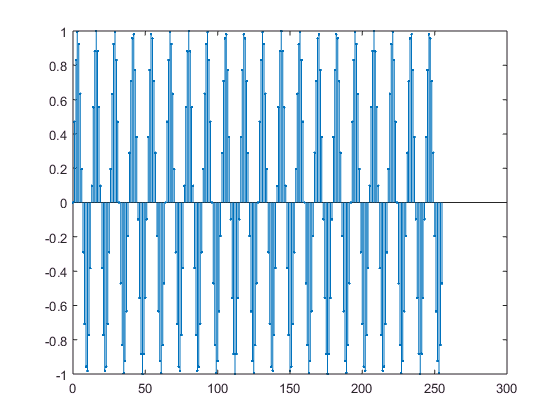

x1 = sin(2*pi*f1*t);
n = 0:N-1;
stem(n,x1,'.')

Der skal laves en 256-punkts DFT af funktionen, udført med FFT.

FFT-funktionen kan studeres:

help fft

 fft Discrete Fourier transform.
    fft(X) is the discrete Fourier transform (DFT) of vector X.  For
    matrices, the fft operation is applied to each column. For N-D
    arrays, the fft operation operates on the first non-singleton
    dimension.
 
    fft(X,N) is the N-point fft, padded with zeros if X has less
    than N points and truncated if it has more.
 
    fft(X,[],DIM) or fft(X,N,DIM) applies the fft operation across the
    dimension DIM.
    
    For length N input vector x, the DFT is a length N vector X,
    with elements
                     N
       X(k) =       sum  x(n)*exp(-j*2*pi*(k-1)*(n-1)/N), 1 <= k <= N.
                    n=1
    The inverse DFT (computed by IFFT) is given by
                     N
       x(n) = (1/N) sum  X(k)*exp( j*2*pi*(k-1)*(n-1)/N), 1 <= n <= N.
                    k=1
 
    See also 

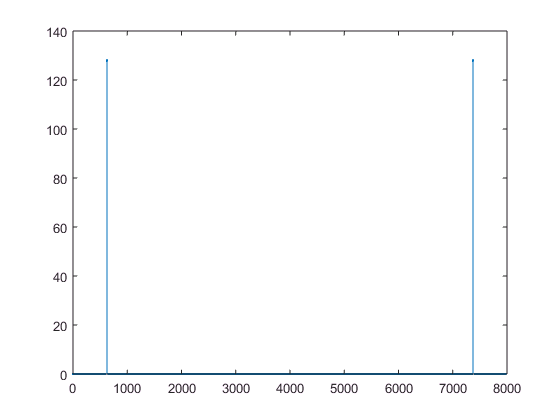


X1 = fft(x1,N);
f = (0:N-1)*fs/N; % 256 frekvenssamples for korrekt skalering af frekvensaksen
stem(f,abs(X1),'.')

Som forventet vises en frekvens på 625 Hz, samt en frekvens på 8000 - 625 Hz = 7375 Hz, da frekvenserne er komplekst konjugeret om DC. Hvis dette ønskes vist bedst muligt, anvendes kommandoen fftshift:

help fftshift

 fftshift Shift zero-frequency component to center of spectrum.
    For vectors, fftshift(X) swaps the left and right halves of
    X.  For matrices, fftshift(X) swaps the first and third
    quadrants and the second and fourth quadrants.  For N-D
    arrays, fftshift(X) swaps "half-spaces" of X along each
    dimension.
 
    fftshift(X,DIM) applies the fftshift operation along the 
    dimension DIM.
 
    fftshift is useful for visualizing the Fourier transform with
    the zero-frequency component in the middle of the spectrum.
 
    Class support for input X:
       float: double, single
 
    See also ifftshift, fft, fft2, fftn, circshift.

    <a href="matlab:doc fftshift">Reference page for fftshift<

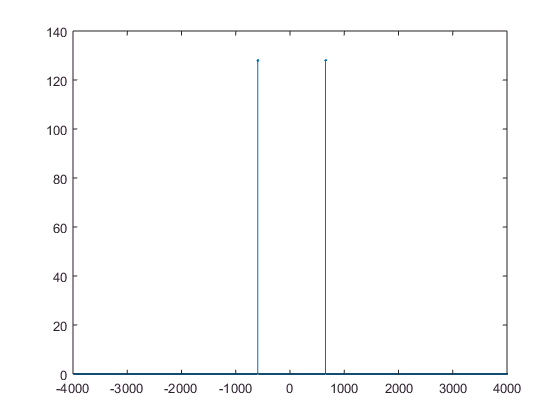

fd = (-N/2+1:N/2)*(fs/N); % 256 frekvenssamples i dobbeltsidet spektrum
X1d = fftshift(X1);
stem(fd,abs(X1d),'.')

Kontroller den kompleks konjugerede symmetri for DFT ved at plotte real(X1), imag(X1) og angle(X1) i stedet for abs(X1). Gør det både den enkeltsidede X1 og dobbeltsidede X1d.

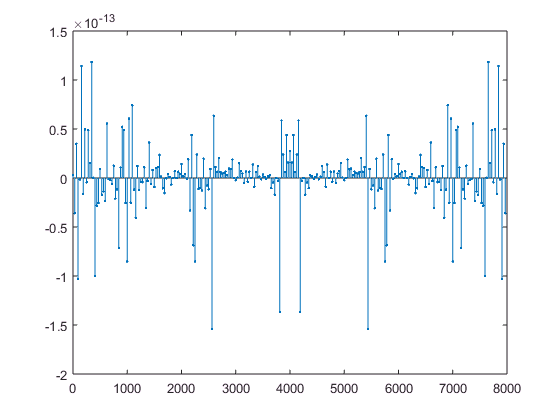

stem(f,real(X1),'.')

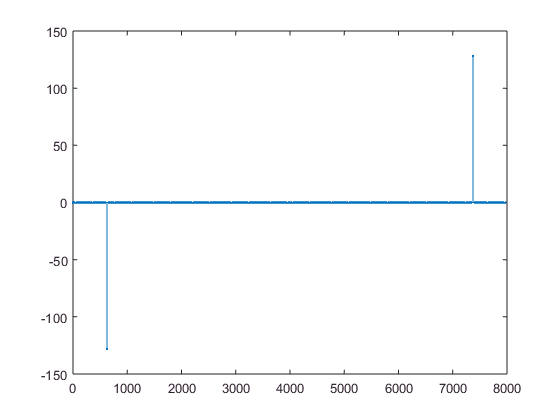

stem(f,imag(X1),'.')

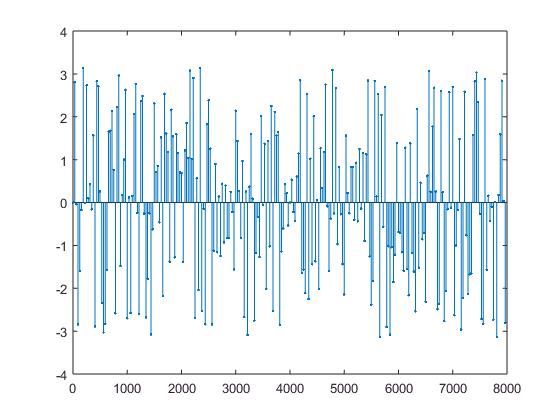

stem(f,angle(X1),'.')

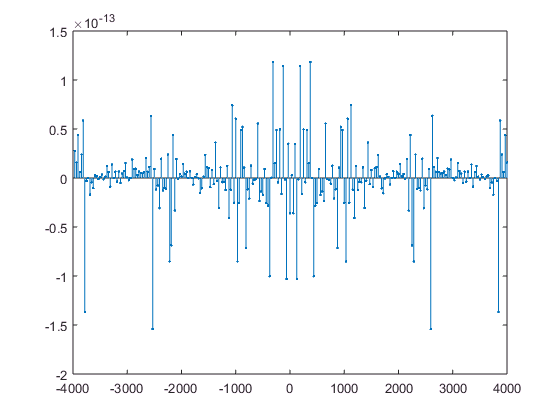


stem(fd,real(X1d),'.')

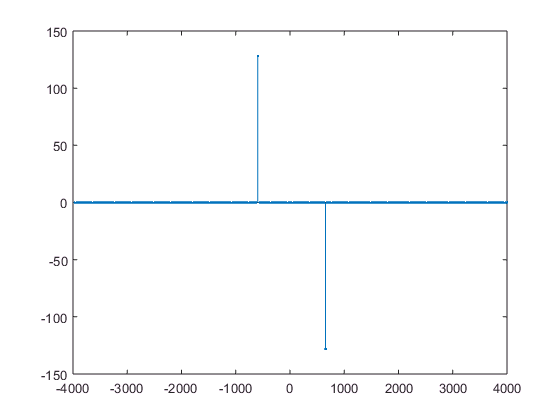

stem(fd,imag(X1d),'.')

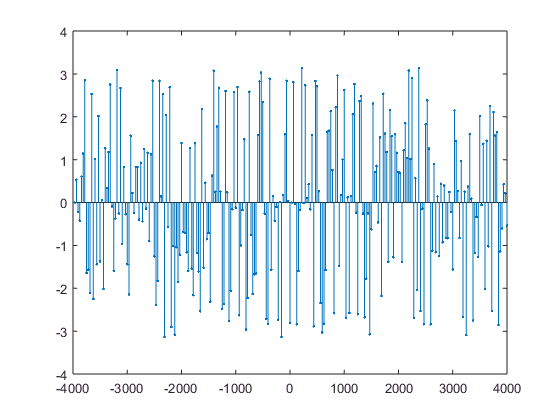

stem(fd,angle(X1d),'.')

Symmetrien gør, at de reelle værdier er spejlet om y-aksen, mens de imaginære værdier (og derfor vinklen) er spejlet både om y- og x-aksen.

Der laves en funktion fftplot(x,N,fs), der nemt plotter et signal og dets DFT med den korrekte frekvenskalering. Dette gøres, så man hurtigere kan plotte senere.

Funktionen tjekkes:

fftplot(x1,N,fs)

**Eksempel B:**

Der prøves igen med en anden frekvens, der er mere tilfældig, således at antallet af perioder ikke er et helt tal inden for samplingområdet.

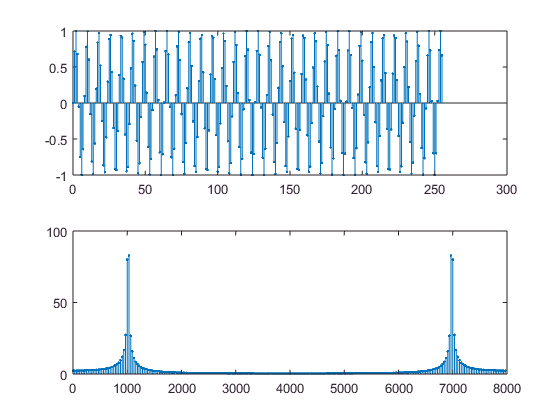

f2 = 1016;
x2 = sin(2*pi*f2*t);
fftplot(x2,N,fs)

Frekvensspektret er ikke pænt her, idet den perfekte sinus bliver ødelagt af sampling-gentagelsen, hvorfor et stort antal forkert frekvenser opstår omkring frekvensen på 1016 Hz. For at få et perfekt frekvensspektrum, skal frekvensen være et heltal ganget på eller divideret fra de oprindelige 625 Hz.

Igen plottes real(X2), imag(X2) og angle(X2) for at undersøge symmetrien:

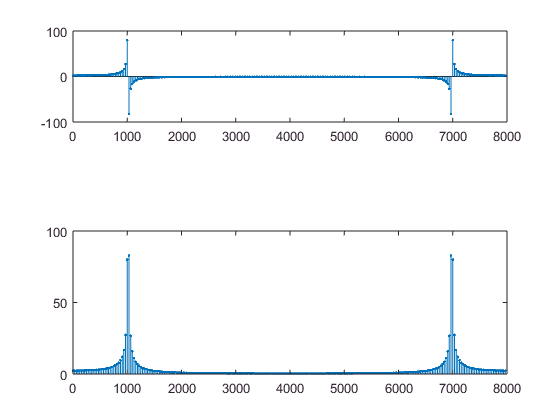

X2 = fft(x2,N);

subplot(3,1,1)
stem(f,real(X2),'.')

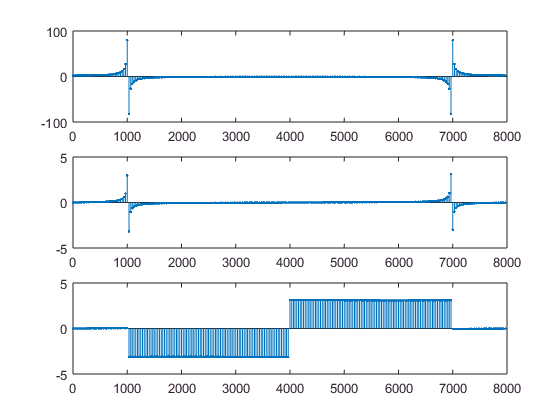

subplot(3,1,2)
stem(f,imag(X2),'.')
subplot(3,1,3)
stem(f,angle(X2),'.')

**Eksempel C:**

Der prøves i dette eksempel hvid støj:

help randn

 randn Normally distributed pseudorandom numbers.
    R = randn(N) returns an N-by-N matrix containing pseudorandom values drawn
    from the standard normal distribution.  randn(M,N) or randn([M,N]) returns
    an M-by-N matrix. randn(M,N,P,...) or randn([M,N,P,...]) returns an
    M-by-N-by-P-by-... array. randn returns a scalar.  randn(SIZE(A)) returns
    an array the same size as A.
 
    Note: The size inputs M, N, P, ... should be nonnegative integers.
    Negative integers are treated as 0.
 
    R = randn(..., CLASSNAME) returns an array of normal values of the 
    specified class. CLASSNAME can be 'double' or 'single'.
 
    R = randn(..., 'like', Y) returns an array of normal values of the
    same class as Y.
 
    The sequence of numbers produced by randn is determined by the settings of


x3 = randn(1,N);
fftplot(x3,N,fs)

Frekvenserne og amplituderne er tilfældige (symmetriske om y-aksen), men ikke konstante, som man ville forvente af ren hvid støj. Dette er formodentlig grundet det begrænsede antal samples.

**Sammenhæng mellem DFT og invers DFT (FFT og invers FFT):**

Der defineres endnu et signal som eksempel:

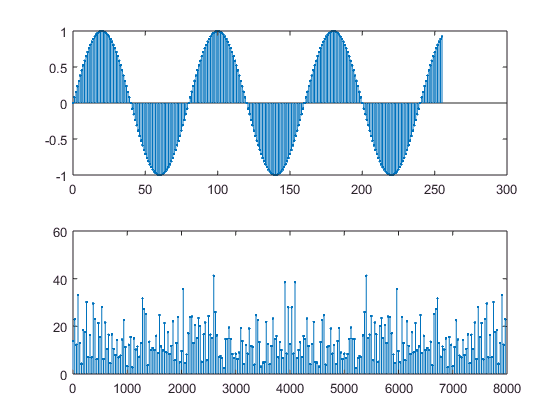

x4 = sin(2*pi*100*t);
subplot(2,1,1)
stem(n,x4,'.')

Der skal undersøges, om fft- og ifft-kommandoerne virkelig er inverse operationer:

help ifft % ifølge help er dette den inverse diskrete FT

 ifft Inverse discrete Fourier transform.
    ifft(X) is the inverse discrete Fourier transform of X.
 
    ifft(X,N) is the N-point inverse transform.
 
    ifft(X,[],DIM) or ifft(X,N,DIM) is the inverse discrete Fourier
    transform of X across the dimension DIM.
 
    ifft(..., 'symmetric') causes ifft to treat X as conjugate symmetric
    along the active dimension.  This option is useful when X is not exactly
    conjugate symmetric merely because of round-off error.  See the
    reference page for the specific mathematical definition of this
    symmetry.
 
    ifft(..., 'nonsymmetric') causes ifft to make no assumptions about the
    symmetry of X.
 
    See also fft, fft2, fftn, fftshift, <a href="matl

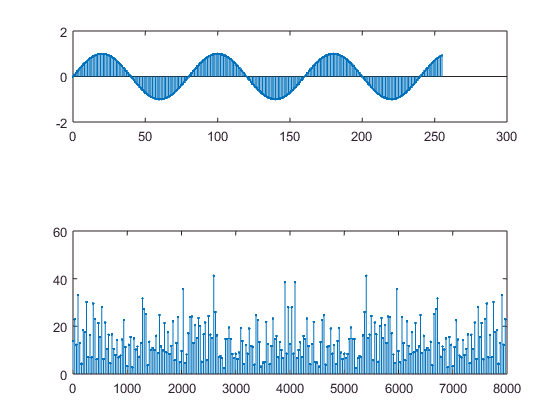

x5 = ifft(fft(x4,N));
subplot(3,1,1)
stem(n,x5,'.')

Det bemærkes, at den inverse operation fungerede.

%s5 = real(x5);
%stem(n,x5,'.')

x4 og x5 plottes sammen:

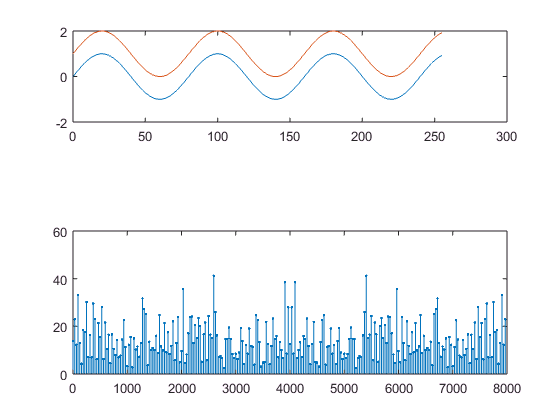

plot(n,x4,n,x5+1)

Dette er som forventet: De er identiske.

**Beregning af invers FFT med FFT-algoritmen:**

Kontroller at den samme algoritme kan bruges til beregning af både FFT og IFFT, idet IFFT(X) = (1/N)FFT(X*)

ifft(fft(x4)) beregnes som før, men denne gang anvendes FFT til beregning af IFFT ud fra ovenstående udtryk

x6 = real((1/N)*fft(conj(fft(x4,N))));
plot(n,x4,n,x6+1)

Denne er også identisk.

## 2. DFT og FFT beregningsmetoder og beregningskompleksitet

Her sammenlignes forskellige slags DFT mht. beregningskompleksitet. Alle beregner den eksakte værdi, og alle er altså lige præcise. Kun hastighed er derfor vigtig.

**Direkte beregning ud fra DFT-definitionen:**

Der laves en funktion, der beregner ud fra definitionen af DFT. Denne kaldes dft_direkte.m og returnerer X, når x og N gives.

Kompleksiteten er teoretisk A1 * N^2 (A1 er en konstant). Dette eftervises ved hjælp af clock og etime, der tracker den anvendte tid:

N = 256;
x = randn(1,N);
help clock, help etime

 clock  Current date and time as date vector.
    C = clock returns a six element date vector containing the current time
    and date in decimal form:
  
       [year month day hour minute seconds]
  
    The sixth element of the date vector output (seconds) is accurate to
    several digits beyond the decimal point. FIX(clock) rounds to integer
    display format.
 
    Note: When timing the duration of an event, use the TIC and TOC
    functions instead of clock or ETIME. These latter two functions are
    based on the system time which can be adjusted periodically by the
    operating system and thus might not be reliable in time comparison
    operations.
 
    See also datevec, datenum, now, etime, tic, toc, 

t = clock;
Xd = dft_direkte(x,N);
t_256=etime(clock,t) % viser den tid, der er gået siden t = clock;

t_256 = 0.0640

Tidsrummet afhænger af processoren, og er derfor ikke konstant. Den er mellem 0.04 og 0.07, oftest 0.05.

Herefter øges N til først 512, derefter 1024, 2048 osv. Stiger kompleksiteten som forventet?

N = 512;
x = randn(1,N);
t = clock;
Xd = dft_direkte(x,N);
t_512=etime(clock,t)

t_512 = 0.1400


N = 1024;
x = randn(1,N);
t = clock;
Xd = dft_direkte(x,N);
t_1024=etime(clock,t)

t_1024 = 0.4400


N = 2048;
x = randn(1,N);
t = clock;
Xd = dft_direkte(x,N);
t_2048=etime(clock,t)

t_2048 = 1.6920

512 = 0.15

1024 = 0.5

2048 = 1.8

Kompleksiteten stiger altså kraftigt med N.

**Matrix (vektoriseret) beregning af DFT:**

help dftmtx

 dftmtx Discrete Fourier transform matrix.
    dftmtx(N) is the N-by-N complex matrix of values around
    the unit-circle whose inner product with a column vector
    of length N yields the discrete Fourier transform of the
    vector.  If X is a column vector of length N, then
    dftmtx(N)*X yields the same result as FFT(X); however, 
    FFT(X) is more efficient.
 
    The inverse discrete Fourier transform matrix is
    CONJ(dftmtx(N))/N.
 
    An interesting example is 
 
      D = dftmtx(4)
 
    which returns
 
      D = [1   1   1   1
           1  -i  -1   i     
           1  -1   1  -1
           1   i  -1  -i]
 
    which illustrates why no multiplications are necessary for
    4-point DFTs.
 
    See also fft and ifft.

    Reference page for dftmtx



Der laves funktionen dft_matrix, der tager x og N og returnerer X. Den teoretiske kompleksitet er A2 * N^2, hvor A2 er en konstant.

N = 256;
x = randn(1,N);
t = clock;
Xm = dft_matrix(x,N);
t_256_mtx=etime(clock,t)

t_256_mtx = 0.0200

Tiden er her omkring 0.2 sekunder, og altså hurtigere ved samme N end den anden version.

Herefter øges N som før for at se, om kompleksiteten tilsvarende stiger.

N = 512;
x = randn(1,N);
t = clock;
Xm = dft_matrix(x,N);
t_512_mtx=etime(clock,t)

t_512_mtx = 0.0200


N = 1024;
x = randn(1,N);
t = clock;
Xm = dft_matrix(x,N);
t_1024_mtx=etime(clock,t)

t_1024_mtx = 0.0400


N = 2048;
x = randn(1,N);
t = clock;
Xm = dft_matrix(x,N);
t_2048_mtx=etime(clock,t)

t_2048_mtx = 0.0920

Kompleksiteten vokser ikke helt som forventet. Dog er den hurtigere end den anden.

**Beregning med FFT DIT radix 2:**

Hvis N er en potens af 2, anvendes radix 2 til udregninger, når man bruger FFT i MATLAB. Kompleksiteten er A3*N*log2(N), hvor A3 er en konstant.

N = 256;
x = randn(1,N);
t = clock;
Xf = fft(x,N);
t_256_fft=etime(clock,t)

t_256_fft = 0.0200

Der tjekkes med 2^18 og 2^18-1 for at se, hvordan algoritmen klarer det.

N = 2^18;
x = randn(1,N);
t = clock;
Xf = fft(x,N);
t_2_18_fft=etime(clock,t)

t_2_18_fft = 0.0360


N = 2^18-1;
x = randn(1,N);
t = clock;
Xf = fft(x,N);
t_2_18_1_fft=etime(clock,t)

t_2_18_1_fft = 0.0280

Tiden stiger ikke ret meget, selvom N bliver meget højere.

Det tager dog længere tid for 2^18-1 end 2^18.

## 3. Sammenhæng mellem DTFT og DFT og valg af DFT-længde

Kort illustration af sammenhængen mellem de forskellige udgaver af Fourier-transformation.

**Analogt signal, den "klassiske" Fourier-transformation:**

Der anvendes det tidskontinuerte signal x(t) = e^(-a*t)*u(t), hvor a = 2*pi*30

(Videre info om frekvens- og amplitudespektrum findes i PDF)

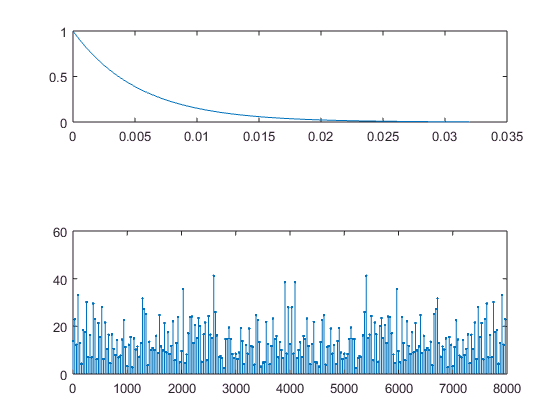

a = 2*pi*30;
t = 0:0.0001:0.032;
xa = exp(-a*t);
plot(t,xa)

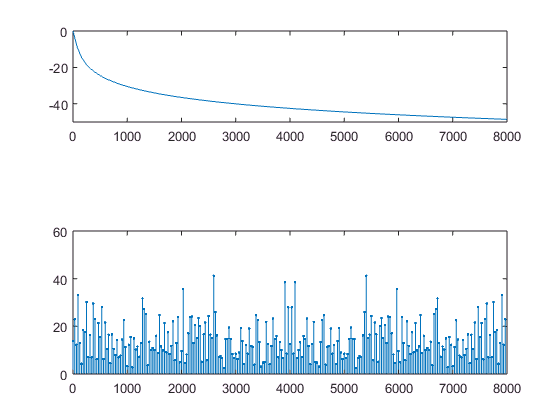


f = 0:80:8000;
Xa = a./(a+j*2*pi*f);
plot(f,20*log10(abs(Xa)))

**Tidssamplet, digital signal, DTFT, diskret-tid Fourier-transformationen:**

Ved sampling af samme signal fås x[n] = x(n*Ts) = (e^(-a*Ts))^n * u[n].

(Videre info om frekvens- og amplitudespektrum findes i PDF)

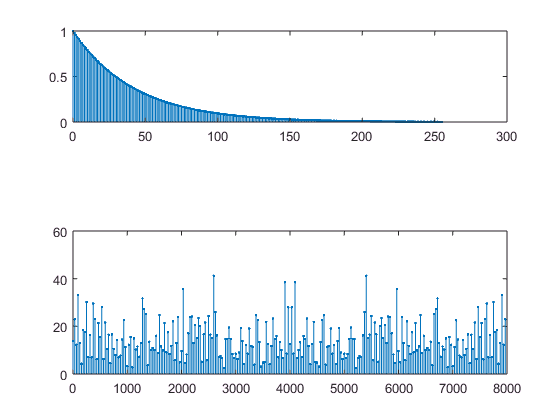

fs = 8000;
Ts = 1/fs;
N = 256;
n = 0:N-1;
x = exp(-a*n*Ts);
stem(n,x,'.')

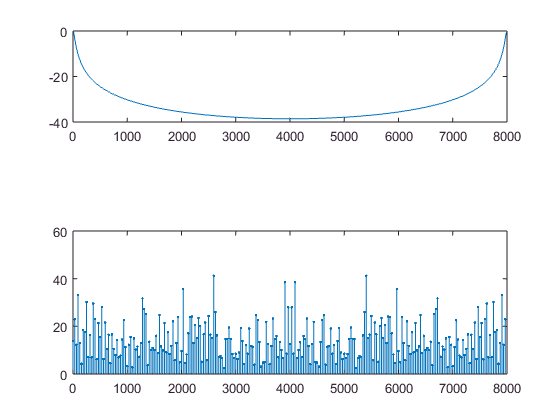


[H f] = freqz(1,[1 -exp(-a*Ts)],1024,'whole',fs);
H = H/H(1); %Normering til 0 dB ved DC
plot(f,20*log10(abs(H)))

**Digitalt signal, samplet i tid og frekvens, DFT, Diskret Fourier-transformation:**

DFT fremkommer af DTFT ved

1) Sampling i frekvens, der beregner N værdier i intervallet fra 0 til fs

2) kun at medtage N samples af x[n]

Denne type kan, modsat forrige, anvendes i beregnes i signalprocessor!

Sampling i frekvens: f = m * fs/N for 0 < m < N-1

Frekvensopløsning: fs/N

Frekvensspektrets udregning kan ses i PDF.

I praksis anvendes FFT til udregning uden tilnærmelser

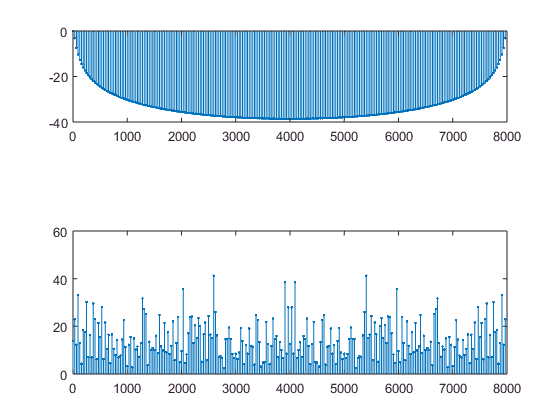

N = 256;
X = fft(x,N);
X = X/abs(X(1)); % Normering
f = (0:N-1)*fs/N;
stem(f,20*log10(abs(X)),'.')

Denne ligner til forveksling DTFT fra forrige sektion.

**Valg af DFT-længde:**

Hvis der kun anvendes 128 samples, fås

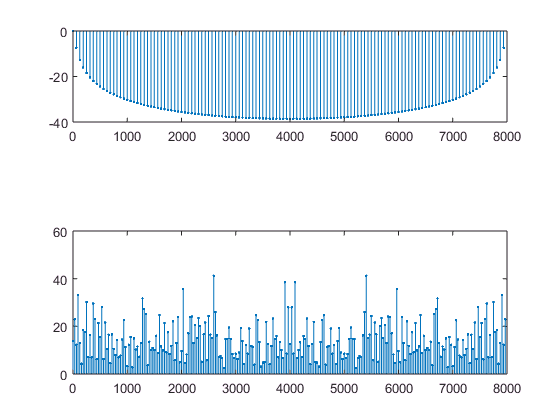

N = 128;
n = 0:N-1;
x128 = exp(-a*n*Ts);
stem(n,x128,'.')

X128 = fft(x128,N);
X128 = X128/X128(1);
f = (0:N-1)*fs/N;

stem(f,20*log10(abs(X128)),'.')